### **1. Negativo de la imagen**

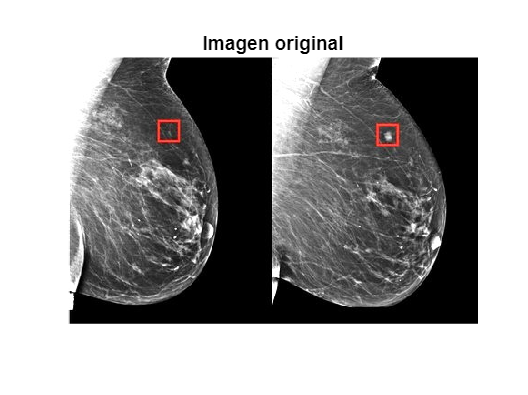

% Leer imagen
imagen_rgb = imread("mamografia.jpg");
imshow(imagen_rgb);
title("Imagen original")

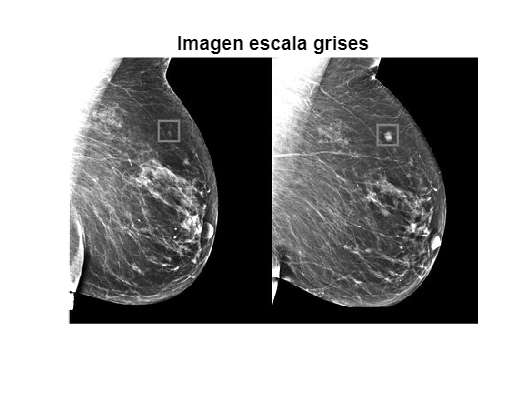


% Convertir a escala de grises
imagen = rgb2gray(imagen_rgb);
figure;
imshow(imagen);
title("Imagen escala grises");

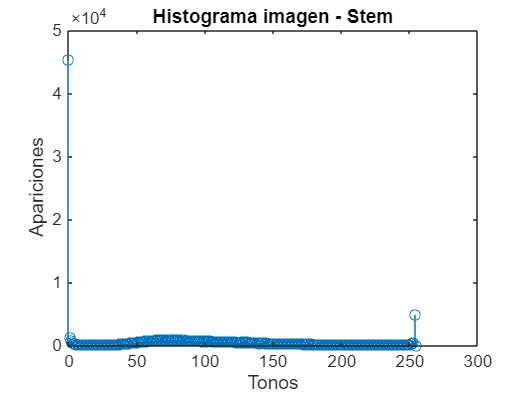


% Crear matriz para colores (histograma)
colores = zeros(256, 1);

% Saber la dimensión de la imagen
[alto, ancho] = size(imagen);

% Contar píxeles para el histograma
for i = 1:alto
    for j = 1:ancho
        tono = imagen(i, j);
        colores(tono + 1) = colores(tono + 1) + 1;
    end
end

% Graficar el histograma
figure;
stem(0:255, colores);
title("Histograma imagen - Stem");
xlabel("Tonos");
ylabel("Apariciones");

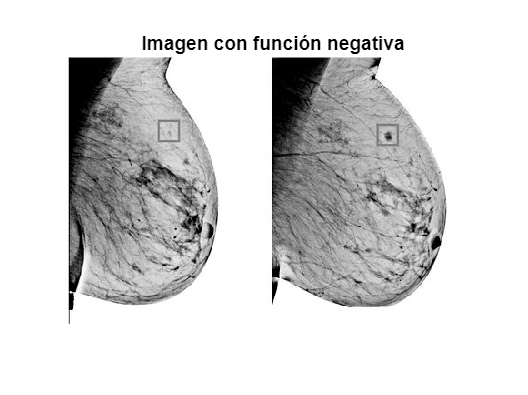


% Desplazamiento de la recta
b = 255;

% Nueva matriz para negativo de imagen
nuevo_color_negativo = zeros(256, 1);

% Nuevos tonos para negativo de imagen
for tono = 0:255
    nuevo_tono = round(b - tono); % Redondear a valores enteros
    nuevo_color_negativo(nuevo_tono + 1) = colores(tono + 1);
end

% Imagen con tonos negativos
imagen_negativa = imagen; % copia de la imagen original

for i = 1:alto
    for j = 1:ancho
        tono_original = imagen(i, j);
        tono_negativo = round(b - tono_original); 
        tono_negativo = max(min(tono_negativo, 255), 0); % Asegurarse de que esté en el rango
        imagen_negativa(i, j) = tono_negativo;
    end
end

% Mostrar la imagen negativa
figure;
imshow(imagen_negativa);
title("Imagen con función negativa");

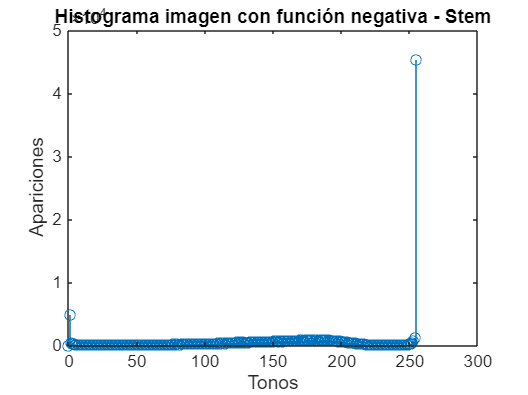


% Graficar el histograma con los tonos negativos
figure;
stem(0:255, nuevo_color_negativo);
title("Histograma imagen con función negativa - Stem");
xlabel("Tonos");
ylabel("Apariciones");

**2. Mapeo de color de 0 a 255**


% Leer imagen
imagen_rgb = imread("mamografia.jpg");
imshow(imagen_rgb);
title("Imagen original")


% Convertir a escala de grises
imagen = rgb2gray(imagen_rgb);
figure;
imshow(imagen);
title("Imagen escala grises");


% Crear matriz para colores (histograma)
colores = zeros(256, 1);

% Saber la dimensión de la imagen
[alto, ancho] = size(imagen);

% Contar píxeles para el histograma
for i = 1:alto
    for j = 1:ancho
        tono = imagen(i, j);
        colores(tono + 1) = colores(tono + 1) + 1;
    end
end

% Graficar el histograma
figure;
stem(0:255, colores);
title("Histograma imagen - Stem");
xlabel("Tonos");
ylabel("Apariciones");

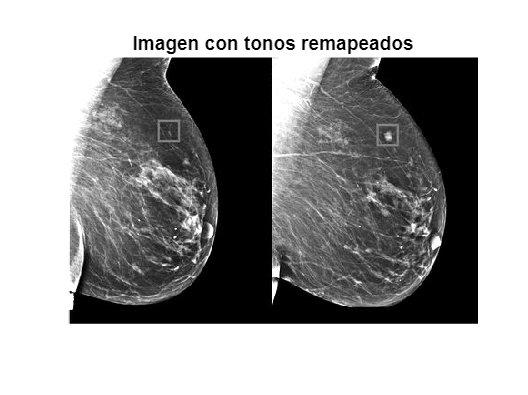


% Índices de los números diferentes de cero
indices = find(colores ~= 0);

% Primer índice diferente de cero
x1 = indices(1);

% Último índice diferente de cero
x2 = indices(end);

% Índices a mapear
y1 = 1;
y2 = 256;

% Pendiente y desplazamiento de la recta
m = (y2 - y1) / (x2 - x1);
b = y1 - m * x1;

% Nueva matriz para los colores mapeados
nuevo_color_mapeado = zeros(256, 1);

% Mapear los tonos de x1-x2 a 0-255
for tono = x1:x2
    nuevo_tono = round(m * tono + b); % Redondear a valores enteros
    nuevo_tono = max(min(nuevo_tono, 256), 1); % Asegurarse que esté entre 1 y 255
    
    % Asignar el valor del tono correspondiente al índice
    nuevo_color_mapeado(nuevo_tono) = colores(tono);
end

% Remapear los tonos de la imagen
imagen_remapeada = imagen;  % copia de la imagen original

for i = 1:alto
    for j = 1:ancho
        tono_original = imagen(i, j);
        
        tono_remapeado = round(m * tono_original + b); 
        tono_remapeado = max(min(tono_remapeado, 255), 0); % Asegurarse de que esté en el rango
        
        % Asignar el nuevo tono a la imagen remapeada
        imagen_remapeada(i, j) = tono_remapeado;
    end
end

% Mostrar la imagen remapeada
figure;
imshow(imagen_remapeada);
title("Imagen con tonos remapeados");

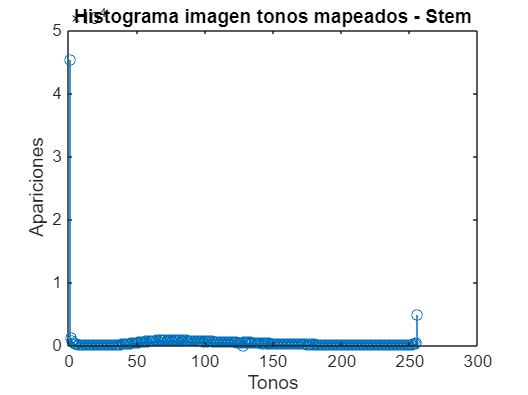


% Graficar el histograma con los tonos mapeados
figure;
stem(1:256, nuevo_color_mapeado);
title("Histograma imagen tonos mapeados - Stem");
xlabel("Tonos");
ylabel("Apariciones");

**3. Transformación de "triangulo"**

% Leer imagen
imagen_rgb = imread("mamografia.jpg");
imshow(imagen_rgb);
title("Imagen original")


% Convertir a escala de grises
imagen = rgb2gray(imagen_rgb);
figure;
imshow(imagen);
title("Imagen escala grises");


% Crear matriz para colores (histograma)
colores = zeros(256, 1);

% Saber la dimensión de la imagen
[alto, ancho] = size(imagen);

% Contar píxeles para el histograma
for i = 1:alto
    for j = 1:ancho
        tono = imagen(i, j);
        colores(tono + 1) = colores(tono + 1) + 1;
    end
end

% Graficar el histograma
figure;
stem(0:255, colores);
title("Histograma imagen - Stem");
xlabel("Tonos");
ylabel("Apariciones");

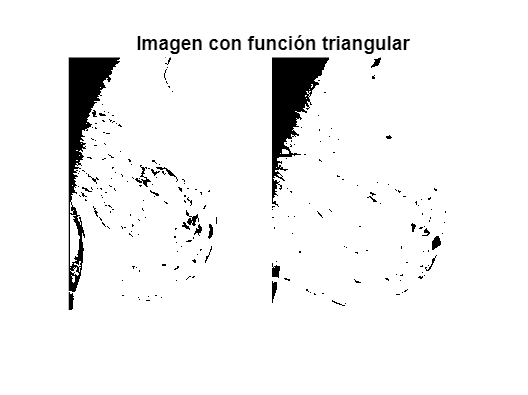


% Para la función triangular
% Definir el rango de x
x = 0:255;  

% Centro del triángulo
b = 127.5;  

% Nueva matriz para los colores mapeados
nuevo_color_triangulo = zeros(256, 1);

% Nuevos tonos para función triangular
for tono = 0:255
    % Triangular function
    nuevo_tono = round(max(min(1 - abs((tono - b) / b), 1), 0) * 255);
    nuevo_color_triangulo(nuevo_tono + 1) = colores(tono + 1);
end

% Imagen con función triangular
imagen_triangulo = imagen; % copia de la imagen original

for i = 1:alto
    for j = 1:ancho
        tono_original = imagen(i, j);
        tono_triangular = round(max(min(1 - abs((tono_original - b) / b), 1), 0) * 255); 
        tono_triangular = max(min(tono_triangular, 255), 0); % Asegurarse de que esté en el rango
        imagen_triangulo(i, j) = tono_triangular;
    end
end

% Mostrar la imagen con función triangular
figure;
imshow(imagen_triangulo);
title("Imagen con función triangular");

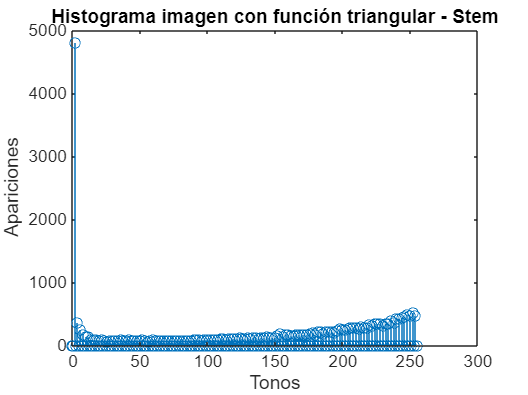


% Graficar el histograma con función triangular
figure;
stem(0:255, nuevo_color_triangulo);
title("Histograma imagen con función triangular - Stem");
xlabel("Tonos");
ylabel("Apariciones");